# Lab #7 FIR Filter Design

## Lab Objectives

- You have learned how to create a simple moving average filter that has a number of coefficients that are all the same value and you have built low pass filters using Windowed SINC impulse responses.  But, the MAV filters are not particularly selective and their selectivity cannot be easily be modified.  There are also instances when we need to reject low frequency content or pass signals with frequencies within a range or reject signals within a specific range.  Therfore, we will learn how to create high pass filters, bandpass and band reject filters from low pass prototypes using techniques discussed in class and from the Smith Text.

- You will also learn how to get the frequency response of a filter from its impulse response using the Fast Fourier Transform FFT.

- You will learn to test characterize sinusoidal input filter performance in the time domain.

- You previously designed a stable, recursive method to compute the running standard deviation of a signal, but we don't always need the standard deviation from the beginning of time.  Therefore, you will learn how to create and implement a faster responding approach to calculating the standard deviation.

## Reading

Chp 14, 16, and 19 in Smith.          http://Arduino.cc 

## Intended Learning Outcomes: 

- Demonstrate high pass filtering of a signal using an FIR filter implemented in a microprocessor

- Demonstrate band pass filtering of a signal using an FIR filter implemented in a microprocessor

- Demonstrate band stop filtering of a signal using an FIR filter implemented in a microprocessor

- Practice communicating your results and your work in writing

## Section 1 – FIR Sinc Filters: Low Pass Filter (LPF) and High Pass Filter (HPF)

### Overview

In this section, you will create an FIR low pass filter with a cutoff frequency of 50 breaths per minute (bpm), and then transform the low pass filter into a high pass filter by spectral inversion.  The sample frequency of the system is 10 Hz, or 600 bpm.  The fractional cutoff frequency is then 50/600 = 0.0833.

The high pass FIR filter is created by starting with a low pass windowed sinc filter kernel at a cutoff frequency of Fc=0.08333 fractional frequency (fraction of the sample rate). Once the kernel is complete, invert the sign of each point in the impulse response of the filter, and then add 1.0 to the middle (M/2) point.  Kernels are implemented in fixed-point integer form, so the value of  "1"  is represented by the value of the kernel scaling fixed point (HFXPT).  The kernel is the impulse response of the high pass filter.

For this section of the lab use the Serial Monitor to view and copy the Arduino output.  You will copy some of this information into MATLAB for analysis.

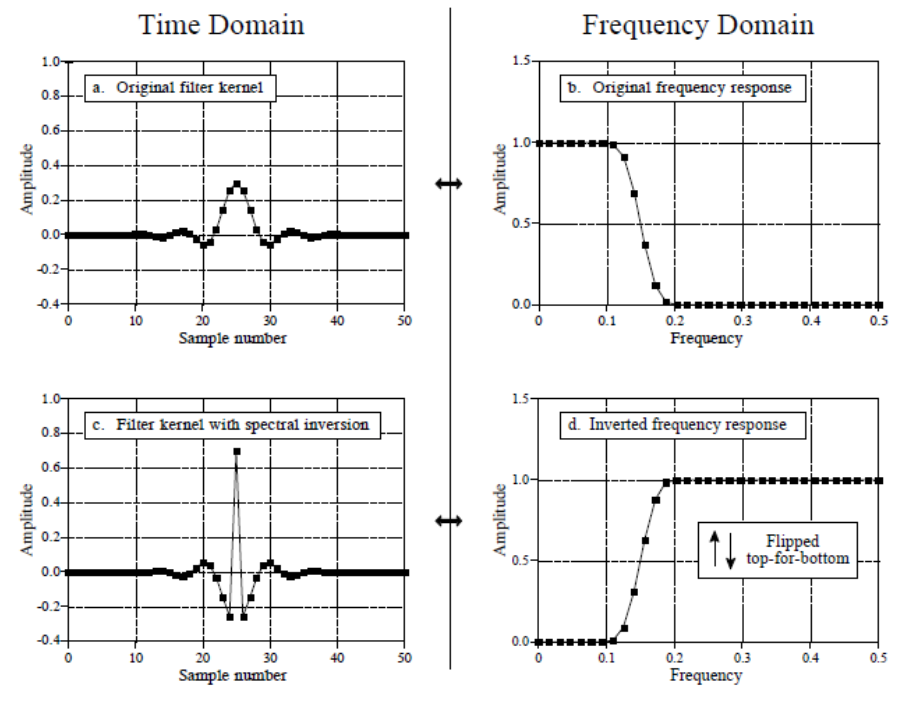

Figure 1. Conversion of a low pass FIR filter kernel into a high pass filter kernel by spectral inversion. Note how the HPF impulse response terms have negative sign for all terms and also the center point of the impulse response is both inverted and has the value 1.0 added to it. In the frequency domain, this results in the spectrum being flipped top for bottom.

### Description of the code

Use the file Lab7_FIR_Section_01_Base_Code.ino for this part of the lab.

The code first creates the windowed sinc Low Pass Filter (LPF), normalizes it for unity DC gain, and maps it to a fixed-point representation. The impulse response is printed out so that you can find the frequency response in MATLAB.  The sketch also prints out a C style declaration section that will be used to create filters in following sections.  

Refer to the comments in the C code for details on what the code is doing.  Become familiar with how the code works.

For this section of the lab use the Serial Monitor to view and copy the Arduino output.  You will copy some of this information into MATLAB for analysis.

**Procedure**

1)  Upload the  sketch and modify the corner frequency of the kernel to 50 Breaths Per Minute (BPM).

2)  Employ the spectral inversion method by writing code for the spectralInvertKernel( ) function in the Arduino C-code.  Verify creation of a correct HPF kernel per the Smith figure above.  Note: the kernels are stored in fixed-point variables and are scaled to retain their resolution.  Use appropriate scaling for the inversion recalling what fixed point number represents the value of 1.  Recall that a spectrally inverted filter can be created from the LPF impulse response by negating each coefficient of the filter except for the middle sample. Create the middle sample of the of the HPF by setting the coefficient to HFXPT minus the middle coefficient of the LPF.

3) For impulse response lengths of 21, 41, 81, copy the impulse  response for the LPF and the HPF to an appropriately named variable in MATLAB. Copy these values from the Serial Monitor into this MATLAB Live Script.  Don't use the CaptureArduinoData.m function.  

The Discrete Fourier Transform (DFT) implemented by the FFT function in MATLAB will be used to find the frequency response of the filter.  To improve the resolution the impulse response will be padded with zeros to a length of 256 samples.  This will change the frequency resolution to

$f_{res} = \frac{f_{sample}}{N}$ where N is the number of points in the impulse response plus the zero-padding.

4)  For each impulse response variable in MATLAB pad each variable with enough zeros to make the length of the impulse response 256.  This can be done by concatenating a vector of zeros to the impulse response.  An easy way to create a vector of zeros is to use the "zeros" function in MATLAB.  I have done this in an example below:

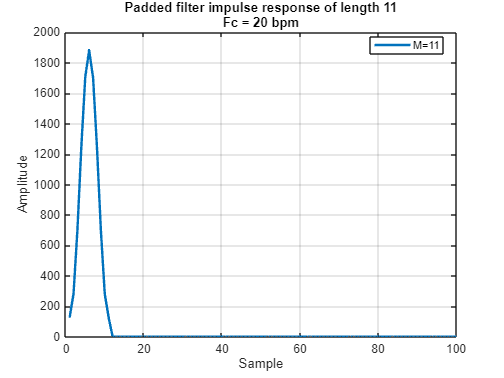

%  Example Code 
%
% Impulse response for LPF of Fc = 20 BPM MFILT = 11 (copied from the
% serial monitor after running the C code on the Arduino).
%

MFILT = 11;
hLPF_11 = [125,280,701,1247,1705,1883,1705,1247,701,280,125];

hLPF_11_padded = [hLPF_11, zeros( 1, 256-MFILT )];
%  Plot the impulse response of the first 101 samples
figure
plot(hLPF_11_padded,'LineWidth',2)
grid on
title(sprintf('Padded filter impulse response of length 11\nFc = 20 bpm'));
xlabel('Sample');
ylabel('Amplitude')
xlim([0,100])

legendStr = {'M=11'};
legend(legendStr,'Location',"best");

**5)  Plot P1 and P2 -- Zero pad each impulse response of length 21, 41 and 81 to a length of 256 samples (lowpass and highpass responses).  Make 1 plot with all three impulse responses for the LPF overlaid on top of one another and another plot with all three impulse responses for the high pass filters overlaid on top of one another.  Only plot the first 101 samples of the impulse responses.  Include both plots P1 and P2 in your report.**

**6) Question Q1 -- In the narrative of your report in your own words (don't just repeat this question) answer which one of the three filters will introduce the most delay in the output signal?  Why?**

%  Zero pad each impulse responseof length 21, 41 and 81 to a length of 256
%  samples.  Plot all three impulse responses on a single graph.  Only show
%  the first 101 samples of each (use the xlim([start, stop]) to limit the
%  x-axis length

%  Put your solution here





7) Find the frequency response of the LPF for each filter length using the DFT.  For a length N sample sequence, the DFT results in $N/2+1$ samples in the frequency domain. These magnitudes represent frequencies from 0 to the Nyquist frequency of $f_{sample}/2$.  There are two sequences that result, one from the magnitude of the COSINE terms and one from the magnitude of the SINE terms.

The 'fft' function in MATLAB computes the discrete fourier transform but for a sequence of N samples it produces N complex output samples.  These represent the frequencies from 0 to $f_{sample}$.  The terms in the output of the FFT are complex values.  The  real part of the value represents the magnitude of the COSINE term in the DFT.  The imaginary part of the output is the magnitude of the SINE term in the DFT.

The syntax for the FFT function is:

%  m = fft( h )

The fft function can also zero pad the input by adding a second argument that determines the length of the FFT.  However, we have already padded the sequence, so use your zero padded sequence.

The magnitude of the frequency response is found using the MATLAB function abs.  

% mag = abs(m)

Recall that the impulse response is scaled by HFXPT in order to use fixed point values.  In order to get the frequency response in the desired units scale each impulse by 1/HFXPT prior to computing the FFT.

An example of computing the FFT of  the impulse response and plotting the frequency response is shown below for the M = 11, Fc = 20 BPM FIR low pass filter.  

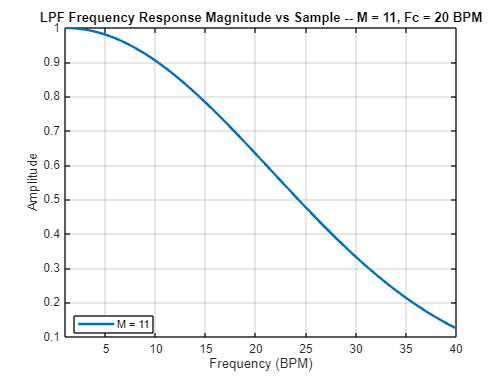

%  Example
%
%  Plot the impulse response of the LPF.  Scale the impulse response by the
%  value of HFXPT

HFXPT_LPF = 10000;



%  Find the frequency response.  Scale the impulse response by the value of
%  HFXPT

[mLPF_11] = fft( hLPF_11_padded/HFXPT_LPF );


%  Plot the magnitude of the frequency response versus sample number.  Plot
%  just the first 40 bins or samples

figure
plot(abs(mLPF_11),'LineWidth',2);
grid on
title('LPF Frequency Response Magnitude vs Sample -- M = 11, Fc = 20 BPM')
xlabel('Frequency (BPM)');
ylabel('Amplitude');
xlim([1,40])

legendStr = {'M = 11'};
legend(legendStr,'Location',"best")

**4) PLOT P3 --- Plot the magnitude of the frequency response for all three low pass filters of length 21, 41, 81 on the same graph below (don't use decibels).  Plot the frequency responses vs the sample number  Limit the x-axis to a range from 0 to 40.  This can be done using the xlim([0,40]) command after plotting the graph.  **


%
%  Find and plot the magnitude of the frequency response of the low pass filters of length 21, 41, 81, Fc = 50 BPM using the fft function in
%  MATLAB.  
%

%  Place your solution here




**7) PLOT P4 -- Plot the magnitude of the frequency response for all three high pass filters of length 21, 41, 81 on the same graph below (don't use decibels).  Plot the frequency responses vs the sample number  Limit the x-axis to a range from 0 to 40.  This can be done using the xlim([0,40]) command after plotting the graph**


%
%  Find and plot the magnitude of the frequency response of the high pass filters of length 21, 41, 81, Fc = 50 BPM using the fft function in
%  MATLAB.  
%

%  Place your solution here





8) The length of the impulse response is padded to 256 samples and the DFT is computed using all 256 samples.  The sampling frequency of the system is 10 Hz (600 bpm).  Each sample is taken at a 10 Hz rate (0.1 Sec/sample).  The 256 point DFT splits the frequency dimension into 256 bins starting at 0 Hz and extending to the sample rate of 10 Hz.  Each bin in the DFT is then 10Hz/256 wide (except the first and the last).

9)  In MATLAB create a row vector of length 256  that represents the fractional frequency for each point in the DFT.  That is the frequency as a fraction of the sampling frequency.  In MATLAB you can easily create a row vector with incrementing value using the syntax below.  This will create a row vector from 0 to 10 in increments of 1 and a row vector from 0 to 10 in increments of 0.2

%  variable = [0:10];   %  row vector with elements 0 to 10 in increments of 1

%  variable2 = [0:.2:10];  %  row vector with elements from 0 to 10 in increments of 0.2


The fractional frequency can be found if you assume that the first frequency is 0 and the last frequency is 255 (256 elements).  The last frequency corresponds to the sample frequency or a fractional frequency of 1.0

**10)  PLOT P5 and P6.  Repeat the plots of the LPF frequency response and the HPF frequency response but use the fractional frequency for the X-axis.  Limit the x-axis to a range from 0 to 0.5, the Nyquist rate.**

%
%  Create a row vector that represents the fractional frequency from 0 to 1
%  of the 256 element DFT. Re-plot the LPF and HPF frequency responses vs
%  the fractional frequency.

%  Place your solution here






11)   In MATLAB create another row vector that represents the frequency in BPM for each point in the DFT.  Recall that the sample rate in BPM is 600.

**12)  PLOT P7 and P8: Repeat the plots from above but use the frequency in BPM for the X axis. Limit the range of the x-axis to 0 to 300 bpm.  **

%
%  Create a row vector that represents the frequency in BPM from 0 to 600
%  of the 256 element DFT. Re-plot the LPF and HPF frequency responses vs
%  the frequency in BPM.

%  Place your solution here





**11) Question Q2: Answer the following question in the narrative of your report.  As the filter length of the FIR filter increases, what is the impact on the sharpness of the filter’s cutoff between passband and stop band?  What is the 10% to 90% transition bandwidth of each filter.  This is the bandwidth between the points that are at 10% of the magnitude and 90% of the final magnitude (also See Smith for definition)**

## Section 2 – FIR Sinc Filters: Band Pass Filter (BPF) and Band Stop Filter (BSF)

### Overview

NOTE: In this section you will use the CaptureArduinoData.m function so you can save the output from the Arduino to MATLAB.

For breath rate analysis, we may wish to identify if a signal has frequencies within a safe range.  We may also be interested if a signal has frequencies outside a safe range.

To identify frequencies within a range we can use a Band Pass Filter (BPF) that passes only the frequencies within an acceptable range for analysis.  We can then analyze what is coming through the filter and determine if the signals are at an acceptable level.

To identify frequencies that are outside of a safe range we can use a Band Stop Filter (BSF).  A band stop filter will attenuate all signals within a range of frequencies and allow all others to pass through.  If we attenuate the desired frequencies and allow the undesired frequencies we can analyze whether we have an unacceptable level of undesired frequencies.

Bandpass filters may be constructed by placing a lowpass filter and a highpass filter in cascade (series) with one another.as shown from the following figures from Smith.  Recall that for a BPF the lowpass filter must have a corner frequency that is higher than the corner frequency of the highpass filter.  Otherwise nothing will pass through the filter.  The lowpass filter defines the UPPER cutoff frequency of the BPF.  The highpass filter defines the LOWER cutoff frequency of the BPF.

 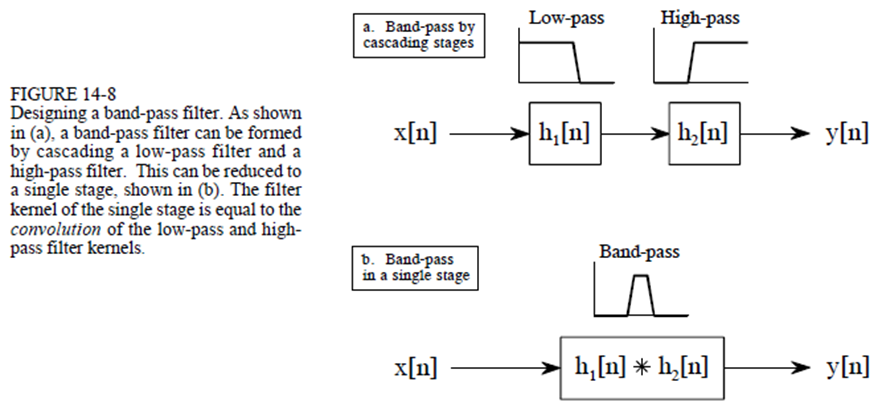

Bandstop filters may be constructed by placing a lowpass filter and highpass filter in parallel with one another and summing their outputs.  These are also shown in the figure below from Smith.  Recall that for a BSF the lowpass filter must have a corner frequency that is lower than the corner frequency of the highpass filter.  Otherwise nothing will attenuated by the filter.

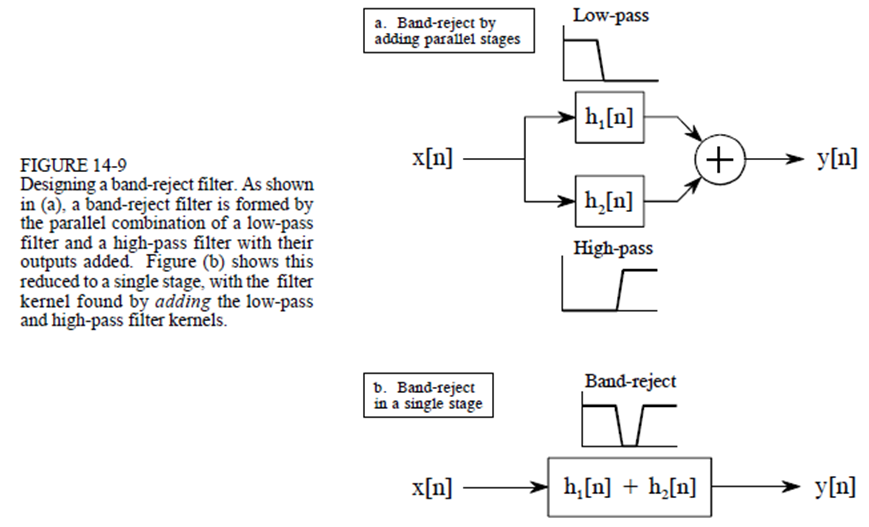

The code in the code base for Lab 7 section 02 implements prototype LPF and HPF sections in fixed point math by using the windowed SINC filters as in  Section 1.  You can use the MATLAB FIR_Designer function to create impulse responses for the LPF and HPF filters.  The function will print out a C style header with the impulse response.  You can copy this code into the appropriate location in the sketch.

Using the MATLAB FIR_Designer.m function you can create impulse responses for LPF and HPF filters with different corner frequencies and impulse response lengths.  You can adjust the corner frequencies and transition bandwidths (by adjusting the impulse response lengths) of the LPF and HPF sections as needed and then combine the filters to build the specified BPF and BSF functions.

Load and execute the code from the file "Lab7_FIR_Section_02_Base_Code.ino". Use it to build and test BPF and BSF filters per the following procedure.

### Procedure/Reporting

1) Using the FIR_Designer MATLAB function tool, design and test the FIR BPF whose specifications are in the code comments and repeated below.

#### **Filter Specifications**

#### **Filter 1 -- Bandpass Filter**

BPF with a lower corner frequency of 15 bpm and a high corner frequency of 50 bpm.  The 10%  to 90% transition BW = 20 bpm  The transition BW is defined as the width (in BPM) of the filter from the 10% magnitude frequency to the 90% magnitude frequency.  The example below shows a LPF with a 10% to 90% transition BW of 90.8 - 69.1 = 21.7 BPM

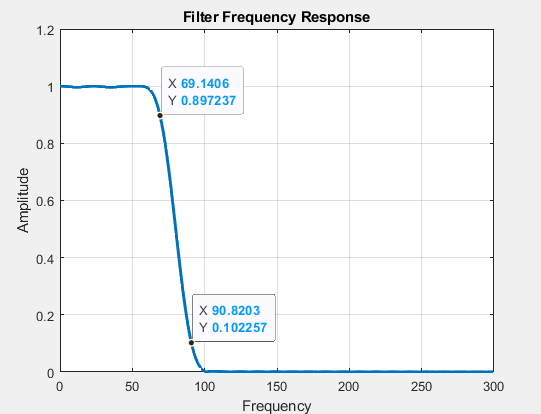

You will modify the the filters using FIR_Designer tool to create the individual LPF and HPF filters and then combine them appropriately to create a BPF response.  This will be an iterative process using MATLAB FIR_Designer tool.  See the figures above on how to combine the filters to create a bandstop response.

2)  Create the individual LPF and HPF filters required to make a BPF using the MATLAB FIR_Designer tool. In MATLAB combine the two filter impulse responses appropriately to create the desired filter response.  Recall that for a BPF the lowpass filter must have a corner frequency that is higher than the corner frequency of the highpass filter.  Otherwise nothing will pass through the filter.  The lowpass filter defines the UPPER cutoff frequency of the BPF.  The highpass filter defines the LOWER cutoff frequency of the BPF.

The FIR_Designer tool will print out the value of HFXPT and the impulse response in a format that is easy to copy into MATLAB.

As a reminder the call to the FIR_Designer function is shown below.  The order of the filter is defined using the Name/Value pair 'nOrder' (e.g. 'nOrder',30).  The 50% cutoff frequency of the filter is defined by the Name/Value pair 'cutBPM' (e.g 'cutBPM',50).  In order to have the C-code header printed you need to specify the argument 'FxdPoint' to true (e.g. 'FxdPoint',true)

%  Example call to FIR_Designer function
%  h = FIR_Designer('nOrder',31,'cutBPM',50,'FxdPoint',true)

NOTE:  Run the FIR_Designer tool in the COMMAND WINDOW.  Do not put it in your MATLAB Live Script!

Once you have an LPF and HPF impulse response then create the impulse response of the BPF.  The impulse response of the BPF is computed by convolving the LPF impulse response with the HPF impulse response.  Use the MATLAB conv function to perform the convolution as shown in the example

### 
$$h_{BPF}[n] = h_{LPF}[n] * h_{HPF}[n]$$


%  h_BPF = conv(h_LPF, h_HPF)

**3)  PLOT P9 -- Plot the impulse response of the BPF.**

**4)  PLOT P10 -- Find the frequency response of the BPF using an FFT of length 256.  Plot the frequency response versus frequency in BPM**

%  Put your solution here.  Use the FIR_Designer tool, but do not run it
%  within the MATLAB Live Editor.  Only run it from the command window.
%  Copy the impulse response printed in the command window into your MATLAB
%  code below for the LPF and the HPF.  Convolve the two responses to create 
%  the final bandpass filter impulse response.  Plot its impulse and frequency
%  response.

%  Place your solution here










2)  Once the design is completed in MATLAB copy the C code header that is printed by the FIR_Designer tool in the command window for the LPF and the HPF filter into the generic filter convolution functions FIR_A and FIR_B that are in the code.  In the "loop" portion of the code modify the code so that a BPF is implemented.  Refer to the block diagrams at the beginning of this section to create a BPF.  

!!!! IMPORTANT !!!! 

In the C-code the two impulse responses are NOT convolved to create the BPF response.  Rather the two filters (LPF and HPF) are run in series with the output of one filter feeding the input of the second filter.  This is equivalent to passing the input to the BPF impulse response created through convolution.

3) In your report include the following:

    a) The impulse response of the BPF filter

    b) The frequency response of the BPF filter using the FFT

    c) The 10% to 90% transition bandwidth of the BPF filter

4)  A test vector generator function is written in the C code to allow testing of the filters using the Arduino.   Test your filter using the built-in test vector generator.  The test vector generator creates three sinusoids in three intervals of time.  They may have different amplitudes if desired.  The parameters of the test vector are adjusted in the code as shown below.

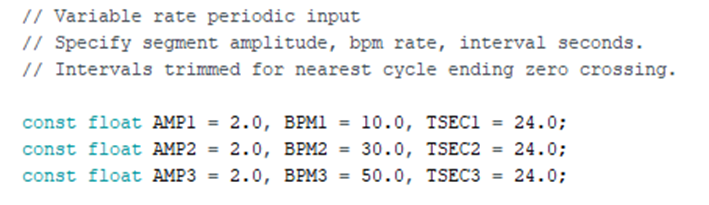                        

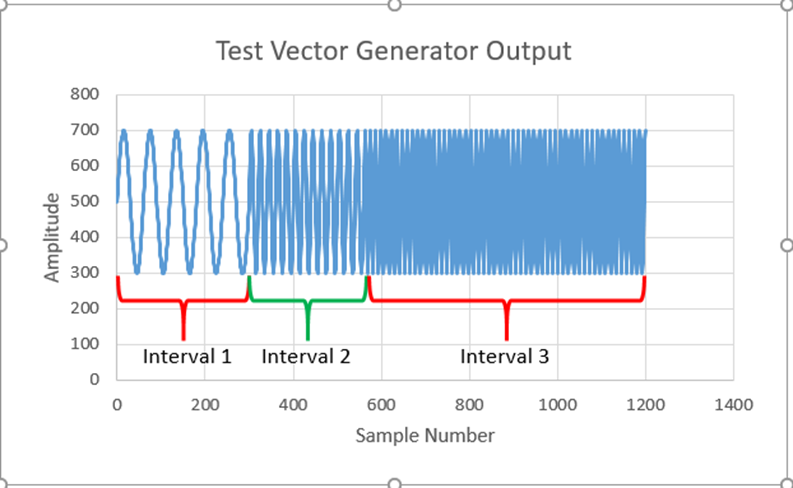      

5) Choose frequencies and interval lengths in the test vector generator to validate BPF filter performance.  Think about what frequencies should be used to verify that your design meets the filter specifications. You want to verify that the filter passes a certain frequency range.  You will want to verify that the filter also attenuates a particular frequency range.  You may want to test your filter with different sets of the three frequencies.

Use the CaptureArduinoData function to capture data from the output of the Arduino and save to a file.  

**PLOT P11 Make a single plot of the input and the output of the bandpass filter.**

6) Compute the attenuation of the frequencies that you used in your test vector generator.  Include a well-annotated chart of these results in your report showing the test frequencies and the attenuation achieved.  Note the stopband attenuation and the passband gains as measured in the time domain.

%
%  Capture the output of the Arduino using the test vector generator
%  output (Use CaptureArduinoData function).  Plot both the input and the
%  output of the filter
%






### **BandStop Filter Design**

7) Build and test the FIR BSF whose specifications are in the code comments and repeated below. 

!!!! IMPORTANT !!!!

In order to add the two impulse responses together, the fixed point scale value HFXPT must be the same for both impulse responses.  In the FIR_Designer tool you can set the value of the fixed point scale value by adding the Name, Value pair "FxdPointScale" followed by the value that is desired.  Example syntax is show below:

% h = FIR_Designer('nOrder', 21,'cutBPM',400, 'Type','HPF','FxdPoint',true, 'FxdPointScale',4096);

#### **Filter 2 -- Bandstop Filter**

BSF with a lower corner frequency of 15 bpm and a high corner frequency of 50 bpm.  The 10%  to 90% transition BW = 20 bpm

!! STRONG SUGGESTION !!

Copy the sketch that you used for the BPF and rename it with an appropriate filename to indicate that it is for a bandstop filter.  This will allow you to go back and use your bandpass sketch if needed

Using the FIR_Designer tool in MATLAB, design an LPF and HPF to meet the requirements of the bandstop filter.  Recall that for a BSF, the LPF will have a corner frequency that is LOWER than the HPF.

You will modify the code in the sketch to include the individual LPF and HPF filters as you did with the BPF.  Then combine them appropriately in the 'loop' section of the code to create a BSF response.  See the figures above on how to combine the filters to create a bandstop response.

**PLOT P12, P13 -- Plot the impulse response and the frequency response of the band stop filter and include them in the your report.**

%  Put your solution here.  Use the FIR_Designer tool, but do not run it
%  within the MATLAB Live Editor.  Only run it from the command window.
%  Copy the impulse response printed in the command window into your MATLAB code below 
%  to create the final bandstop filter and plot its impulse and frequency
%  response.


%  Place your solution here




8)  Test your BSF running on the Arduino using the output of the test vector generator as before.  Choose appropriate frequencies for the generator to properly test the filter performance.

**PLOT P14 -- Plot the input and output of the filter using the test vector generator on the same graph and include the plot in your report.**

9) Demonstrate appropriate band stop performance in the time domain.  Include a well-annotated chart of the result in your report. Note the stopband and passband gains as measured in the time domain.

Here is an example of the output of the test vector generator and the output of a LPF that follows the test vector generator.  Note that as the frequency of the output increases, the low pass filter attenuates the signal.

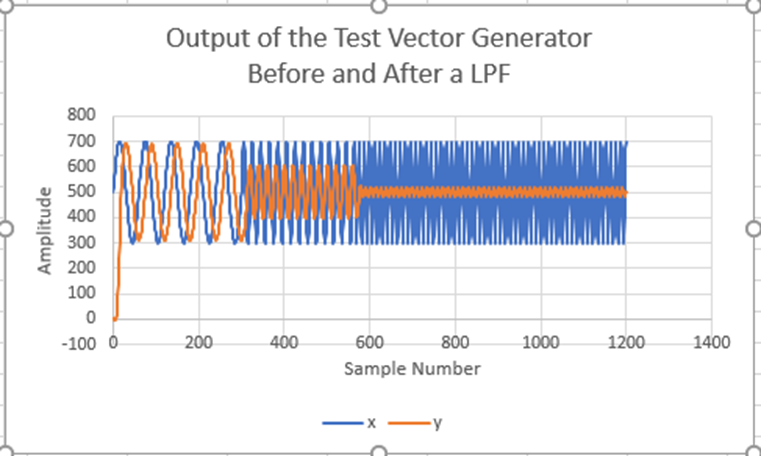

%
%  Capture the output of the Arduino using the test vector generator
%  output (Use CaptureArduinoData function).  Plot both the input and the
%  output of the filter
%


%  Place your solution here






## Section 3 - Resettable Recursive Variance Calculations 

In Lab 2, you implemented a numerically stable, recursive algorithm to calculate the running variance of a signal.  See a typical result below.  Note the lengthy decay toward the true variance of 0.707 after the signal amplitude transition.  Run the sketch from the code base file  "Lab7_FIR_Section_03_Base_Code.ino" to reacquaint yourself with the algorithm.

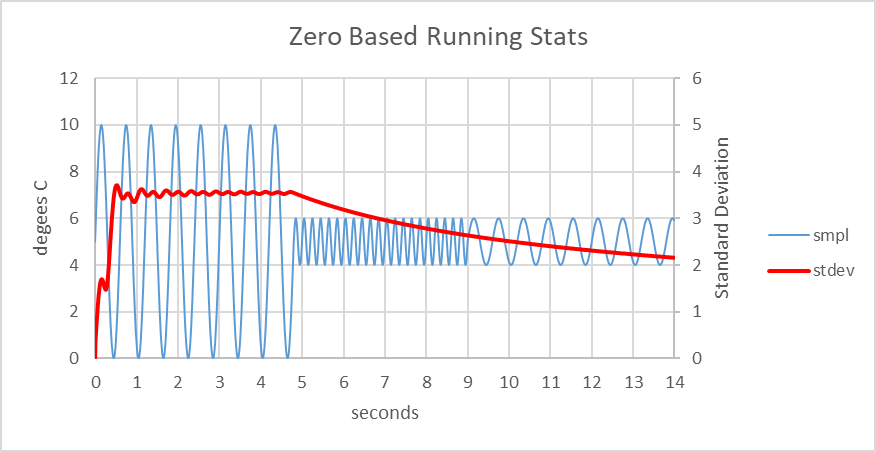

For the application of a breathing monitor, we are not interested in signal energy as measured by the standard deviation from the beginning of time.  Rather, we are interested in the recent standard deviation.  Modify the code to report and hold the running variance every ten seconds (i.e., 100 samples).  Reset the variance and commence a new calculation after each report while holding the last value.  See the stats update example below for varying amplitude and frequency data.  Replicate this chart with your modified code, but reverse the order of modeled amplitude levels.  Include a snip of your code modifications in your report.

**PLOT P15 - Include a plot of your data in your report along with a code snippet in an included appendix.**

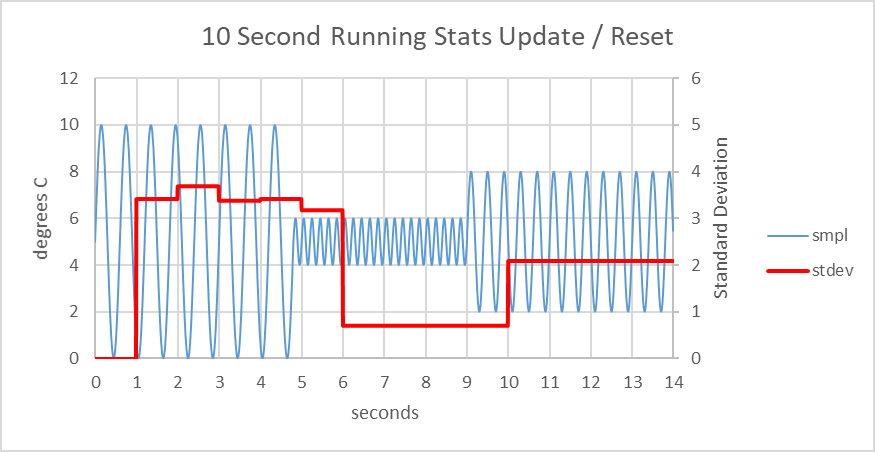

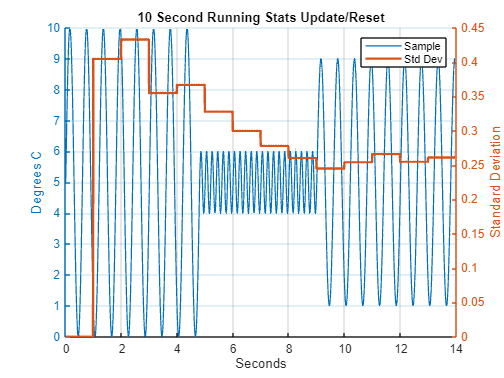

%  Capture the output of the Arduino after modifying the code to implement
%  the resettable statistics.  Plot your results below
filename = 'lab7_section03.mat';
load(filename);

figure
hold('on');
yyaxis left
plot(outData(:,1)./100, outData(:,2), 'LineWidth', 1)
ylabel('Degrees C');
yyaxis right
plot(outData(:,1)./100, outData(:,3), 'LineWidth', 2)
ylabel('Standard Deviation');
hold('off');
legend('Sample','Std Dev');
grid('on');
title('10 Second Running Stats Update/Reset')
xlabel('Seconds');

## Lab Write Up

For your lab write up include the plots as described in the procedure.  Write your report as a story that you are telling someone.  Discuss what you did and the observations that you made.  Write the answers to the questions from the procedure within the narrative.  Don't just repeat the question, write it in your own words along with your answer to the question.  Be sure to use the IEEE format from the Word document.  Don't change any of the fonts, margins, spacings etc..  

## Grading Rubric